# Project Part 2.2

clear
close all
clc


## Parameters

A = [
    0 1;
    880.87 0
    ];
B = [0 -9.9453]';
C = [708.27 0];

x0_0 = [3 50]';
% xi_0 = randn(2,1);
xi_0 = [-6.156018814668943;7.480767837039851];

eigsType = "step";
configuration = "B";
tfin = 10;

dis = 1;            % Variance of white gaussian noise

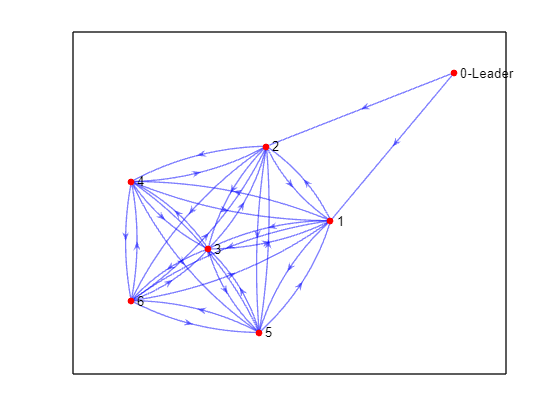

if configuration == "A"
    % Snake configuration
    Adj = [
        0 0 0 0 0 0;
        1 0 0 0 0 0;
        0 2 0 0 0 0;
        0 0 3 0 0 0;
        0 0 0 4 0 0;
        0 0 0 0 5 0
    ];
    G = diag([500 zeros(1,5)]);
    augmented = [zeros(1,7); [5 zeros(1,5)]' Adj];
elseif configuration == "B"
    % Full mesh configuration
    Adj = [
        0 1 1 1 1 1;
        1 0 1 1 1 1;
        1 1 0 1 1 1;
        1 1 1 0 1 1;
        1 1 1 1 0 1;
        1 1 1 1 1 0
    ];
    G = diag([3 3 0 0 0 0]);
    augmented = [zeros(1,7); [3 3 0 0 0 0]' Adj];
else
    % Ring mesh configuration
    Adj = [
        0 0 0 0 0 6;
        2 0 0 0 0 0;
        0 3 0 0 0 0;
        0 0 4 0 0 0;
        0 0 0 1 0 0;
        0 0 0 0 5 0
    ];
    G = diag([10 zeros(1,5)]);
    augmented = [zeros(1,7); [10 zeros(1,5)]' Adj];
end

graph_plot(augmented);


D = diag([sum(Adj(1,:)) sum(Adj(2,:)) sum(Adj(3,:)) sum(Adj(4,:)) sum(Adj(5,:)) sum(Adj(6,:))]);

L = D - Adj;

lambda_i = eig(L+G);

c = 1/(2*min(real(lambda_i)))+1;
Q = 20*eye(2); 
R = 0.1;

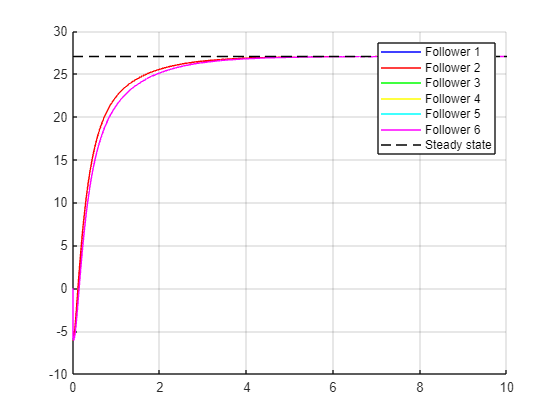

if eigsType == "step" 
    eigs = [0 -4];
elseif eigsType == "ramp" 
    eigs = [0 0];
elseif eigsType == "sinusoidal"
    eigs = [-2i, 2i];
end

Ko = acker(A, B, eigs);

P = are(A-B*Ko,B*R^-1*B',Q);
K = R^-1*B'*P;

P = are((A-B*Ko)',C'*R^-1*C,Q);
F = P*C'*R^-1;

eigL1 = [-20 -50];
L1 = place(A', C', eigL1)';

open("Simulation.slx");
states = sim("Simulation.slx");

close
figure(2)
if eigsType == "step"
    val = max(states.states.Data(:,1));
elseif eigsType == "ramp"
    i = 1;
    while states.states.Data(i+1,2) >= states.states.Data(i,2)
        i = i+1;
    end
    val = min(states.states.Data(i:end,2));
end
hold on
j = 1;
colors = ["Blue", "Red", "Green", "Yellow", "Cyan", "Magenta"];

if eigsType == "step"
    start = 3;
    terminate = 13;
elseif eigsType == "ramp"
    start = 4;
    terminate = 14;
end

for i=start:2:terminate
    plot(states.states.Time,states.states.Data(:,i), Color=colors(j))
    j = j+1; 
end

plot(states.states.Time, val*ones(size(states.states.Data(:,1))), '--', Color="Black")
legend("Follower 1", "Follower 2", "Follower 3", "Follower 4", "Follower 5", "Follower 6", "Steady state")
grid on
hold off

RMSE = mean(states.rms.Data)

RMSE = 1.9180e+03

t = 0;
dim = size(states.states.Data);
pos = zeros(dim(1),6);
for i=1:dim(1)
    for j=1:6
        if eigsType == "step"
            pos(i,j) = states.states.Data(i,2*j+1);
        elseif eigsType == "ramp"
            pos(i,j) = states.states.Data(i,2*j+2);
        end
    end
end

best = 0;
for i=1:length(states.rms.Data)
    if min(pos(i,:)) >= val*0.99 && max(pos(i,:)) <= val*1.01
        if best == 0
            t = states.rms.Time(i);
        end
        best = 1;
    else
        best = 0;
    end
end
t

t = 4

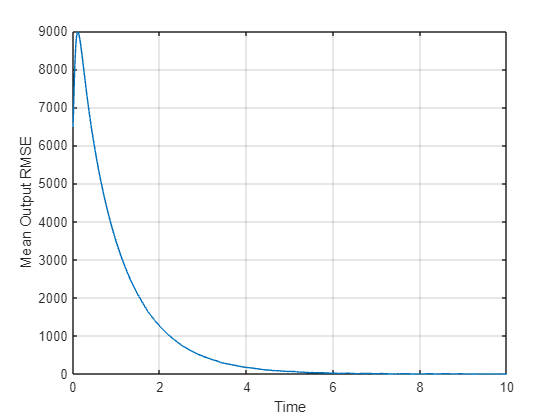


figure(3);
plot(states.rms.Time, states.rms.Data);
xlabel("Time");
ylabel("Mean Output RMSE");
grid

mean(states.ynorm2.Data)

ans = 2.8523e+08

mean(states.unorm2.Data)

ans = 502.4388